% Input:
% H_train [64 x 160 x 2,000]
% H_test [64 x 160 x 5,000]

clear; clc;
rng(47);

% Parameters
na = 64;                % # of BS antennas
nc = 160;               % # of OFDM subcarriers
nTrain = 5000;          % # of training samples
nTest = 2000;           % # of test samples
CR = 16;                % Compression ratio
BTot = 256*5;           % Total feedback bits
snrTrain = -1;          % Noise level in training samples. Value in linear units: -1=infdB or 1=0dB, 10=10dB, 1000=30dB
snrTest = -1;           % Noise level in test samples. Value in linear units: -1=infdB or 1=0dB, 10=10dB, 1000=30dB
quantization = true;    % Quantize or not the compressed CSI
reduce_overhead = true; % Reduce or not the offloading overhead

## Import and preprocess data

fprintf('Importing and preprocessing data...\n')

Importing and preprocessing data...



H_train = load('H_train.mat').H_train;
H_test = load('H_test.mat').H_test;

% UL Training
HUL_train_n = H_train;
Lambda = squeeze(1 ./ mean(abs(HUL_train_n).^2,[1 2]));
if snrTrain ~= -1
    nPower = 1./(Lambda * snrTrain);
    HN = bsxfun(@times,randn(na,nc,nTrain) + 1i * randn(na,nc,nTrain),reshape(sqrt(nPower/2),1,1,[]));
    HUL_train_n = H_train + HN;
    Lambda = squeeze(1 ./ mean(abs(HUL_train_n).^2,[1 2]));
end
HUL_train_n = bsxfun(@times,HUL_train_n,reshape(sqrt(Lambda),1,1,[]));
HUL_train_compl_tmp = reshape(HUL_train_n,na*nc,nTrain).'; %_tmp
HUL_train_compl_tmp_mean = mean(HUL_train_compl_tmp); %
HUL_train_compl = bsxfun(@minus, HUL_train_compl_tmp, HUL_train_compl_tmp_mean); %


% DL Testing
HDL_test_n = H_test;
Lambda = squeeze(1 ./ mean(abs(HDL_test_n).^2,[1 2]));
HDL_test = bsxfun(@times,HDL_test_n,reshape(sqrt(Lambda),1,1,[]));
if snrTest ~= -1
    for q = 1:nTest
        nPower = mean(abs(H_test(:,:,q)).^2,'all')/snrTest;
        HDL_test_n(:,:,q) = H_test(:,:,q) + sqrt(nPower/2) * (randn(na,nc) + 1i * randn(na,nc));
    end
    Lambda = squeeze(1 ./ mean(abs(HDL_test_n).^2,[1 2]));
end
HDL_test_n = bsxfun(@times,HDL_test_n,reshape(sqrt(Lambda),1,1,[]));
HDL_test_compl_tmp = reshape(HDL_test_n,na*nc,nTest).'; %_tmp
HDL_test_compl = bsxfun(@minus, HDL_test_compl_tmp, HUL_train_compl_tmp_mean); %

## Learn Compression (PCA training)

fprintf('Training PCA...\n')

Training PCA...



coeff_ori = pca(HUL_train_compl);

## Reduce Offloading Overhead

if reduce_overhead
    fprintf('Reducing offloading overhead...\n')
    
    coeff = zeros(size(coeff_ori));
    for i = 1:size(coeff,2)
        pcDFT = fftn(reshape(coeff_ori(:,i),sqrt(na),sqrt(na),nc));
        pcDFT = pcDFT(:);
        mask = zeros(size(pcDFT));
        [~,locs] = maxk(abs(pcDFT),na*nc/CR);
        mask(locs) = 1;
        pcDFT = pcDFT .* mask;
        coeff_tmp = ifftn(reshape(pcDFT,sqrt(na),sqrt(na),nc));
        coeff(:,i) = coeff_tmp(:);
    end
    coeff = func_gram_schmidt(coeff(:,1:500));
else
    coeff = coeff_ori;
end

Reducing offloading overhead...


## Learn Quantization (k-means clustering training)

warning('off', 'stats:kmeans:FailedToConverge')

if quantization
    fprintf('Training k-means clustering...\n')
    
    zUL_train = HUL_train_compl * coeff;
    zUL_train_entries = cat(3,real(zUL_train), imag(zUL_train));
    
    importances = var(zUL_train);
    
    Bs = func_allocate_bits(BTot, importances, zUL_train_entries);
    C = length(Bs);
    
    zUL_train_entries_scaled = zeros(nTrain,C,2);
    for i = 1:C
        zUL_train_entries_scaled(:,i,:) = zUL_train_entries(:,i,:) / sqrt(importances(i));
    end
    nTrainKMeans = min(nTrain, round(1e5/C)); % kmeans is trained on 1e5 samples
    zUL_train_entriesCSCG = reshape(zUL_train_entries_scaled(1:nTrainKMeans,1:C,:),nTrainKMeans*C,2);
    quantLevelsCSCG = cell(1,Bs(1));
    for i = 1:Bs(1)
        [~, quantLevelsCSCG{i}] = kmeans(zUL_train_entriesCSCG,2^i);
    end
    
    quantLevels = cell(1,C);
    for i = 1:C
        quantLevels{i} = quantLevelsCSCG{Bs(i)} * (sqrt(importances(i)));
    end
end

Training k-means clustering...


Considering bTot: 100
Considering bTot: 200
Considering bTot: 300
Considering bTot: 400
Considering bTot: 500
Considering bTot: 600
Considering bTot: 700
Considering bTot: 800
Considering bTot: 900
Considering bTot: 1000
Considering bTot: 1100
Considering bTot: 1200


## Testing

fprintf('Testing...\n')

Testing...



coeff = coeff(:,1:C);
zDL = HDL_test_compl * coeff;

if quantization
    for i = 1:size(zDL,1)
        for j = 1:size(zDL,2)
            [~,vecIdx] = (min(abs(zDL(i,j) - (quantLevels{j}(:,1) + 1i * quantLevels{j}(:,2)))));
            zDL(i,j) = quantLevels{j}(vecIdx,1) + 1i * quantLevels{j}(vecIdx,2);
        end
    end
end
HDL_reconst_tmp = zDL * coeff';
HDL_reconst = bsxfun(@plus, HDL_reconst_tmp, HUL_train_compl_tmp_mean);
HDL_ori_reconst = reshape(HDL_reconst.',na,nc,nTest);

## Assessing performance

fprintf('Assessing performance...\n')

Assessing performance...


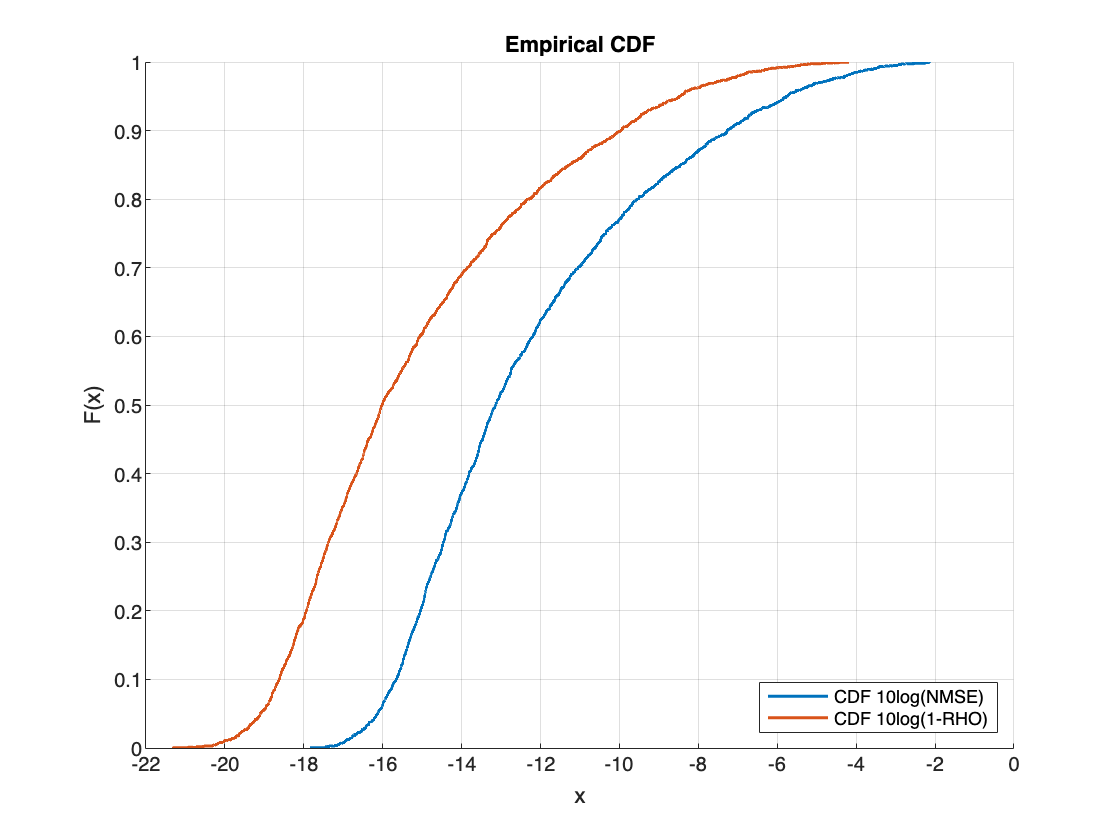


nmse = zeros(nTest,1);
rho = zeros(nTest,1);

for i = 1:nTest
    ch = HDL_test(:,:,i);
    ch_h = HDL_ori_reconst(:,:,i);
    nmse(i) = func_nmse(ch_h,ch);
    rho(i) = func_rho(ch_h,ch);
end

figure;
LineW = 1.5;
hold on;
p1 = cdfplot(10*log10(nmse));
p2 = cdfplot(10*log10(1-rho));
set(p1, 'linewidth', LineW);
set(p2, 'linewidth', LineW);
set(gca,'XLim',[-22,0],'XTick',-22:2:0);
legend('CDF 10log(NMSE)','CDF 10log(1-RHO)','location','southeast');


save(['nmse-BTot',num2str(BTot),'-CR',num2str(CR),'.mat'],'nmse')
save(['rho-BTot',num2str(BTot),'-CR',num2str(CR),'.mat'],'rho')